clear
close all


flag_mod = 0; % force to close the loop
flag_fft = 0;

FS_DAQ = 1000;
FS_CS = 8000;


% for noise test
% time_init = 0.967;
time_test = 39.9; % used for extracting data
Range_time = [0 40]; % used just for plotting
Range_current = [-25 25]; %uA


Range_voltage = [-5 5]; %kV
Range_charge = [-5 5]; %uC
Range_freq = [0 4000];
Range_PSD = [-130 -60];





## Capacitor test

% % 
% % FName(1).name = 'raw_KTI_020_r_50kV_000Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_25_1613_16_DAQ.dat';
% % FName(1).text = 'capacitor 1000pF | 0.5kV/s';
% FName(1).name = 'raw_KTI_002_r_50kV_000Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_25_1630_33_DAQ.dat';
% FName(1).text = 'capacitor 1000pF | 0.5kV/s | K current';
% FName(1).time_init = 0.971;
% 
% FName(2).name = 'raw_KTI_002_r_50kV_001Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_25_1642_02_DAQ.dat';
% FName(2).text = 'capacitor 1000pF | 1kV/s | K current';
% FName(2).time_init = 0.9365;
% 
% FName(3).name = 'raw_KTQ_020_r_50kV_000Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_25_1651_59_DAQ.dat';
% FName(3).text = 'capacitor 1000pF | 0.5kV/s | K charge';
% FName(3).time_init = 0.967;
% 
% FName(4).name = 'raw_KTQ_020_r_50kV_000Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1442_35_DAQ.dat';
% FName(4).text = 'capacitor 1000pF | 0.5kV/s | K charge';
% FName(4).time_init = 0.97;
% 
% FName(5).name = 'raw_KTQ_020_r_50kV_001Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1445_24_DAQ.dat';
% FName(5).text = 'capacitor 1000pF | 0.5kV/s | K charge';
% FName(5).time_init = 0.98;
% 
% FName(6).name = 'raw_KTQ_020_r_50kV_001Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1451_30_DAQ.dat';
% FName(6).text = 'capacitor 1000pF | 1kV/s | K charge';
% FName(6).time_init = 0.987;
% 
% FName(7).name = 'raw_KTI_002_r_50kV_000Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1631_27_DAQ.dat';
% FName(7).text = 'capacitor 1000pF | 0.5kV/s | K charge';
% FName(7).time_init = 0.965;
% 
% FName(8).name = 'raw_KTI_002_r_50kV_001Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1634_17_DAQ.dat';
% FName(8).text = 'capacitor 1000pF | 1kV/s | K charge';
% FName(8).time_init = 0.977;
% 
% Range_current = [-3 3]; %uA


## Resistor test


FName(1).name = 'raw_KTI_200_r_50kV_000Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1616_31_DAQ.dat';
FName(1).text = 'resistor 200Mohm | 0.5kV/s';
FName(1).time_init = 0.967;

FName(2).name = 'raw_KTI_200_r_50kV_001Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1620_44_DAQ.dat';
FName(2).text = 'resistor 200Mohm | 1kV/s';
FName(2).time_init = 0.97;

Range_current = [-25 25]; %uA
Range_charge = [-50 300]; %uC


fName_DAQ = 'raw_KTI_200_r_50kV_000Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1616_31_DAQ.dat'

fName_Current = 'raw_KTI_200_r_50kV_000Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1616_31_current_data.dat'

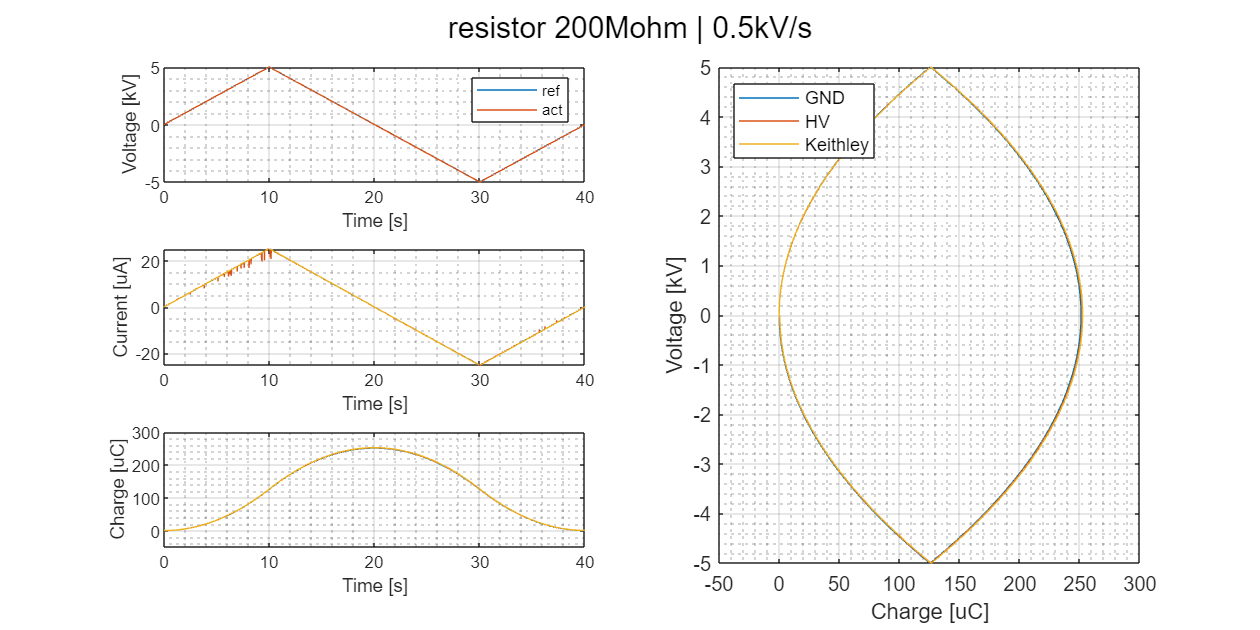

fName_DAQ = 'raw_KTI_200_r_50kV_001Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1620_44_DAQ.dat'

fName_Current = 'raw_KTI_200_r_50kV_001Hz_1000Hz_0000duty_02exp_000deg_000deg_000deg_000deg_2023_12_26_1620_44_current_data.dat'

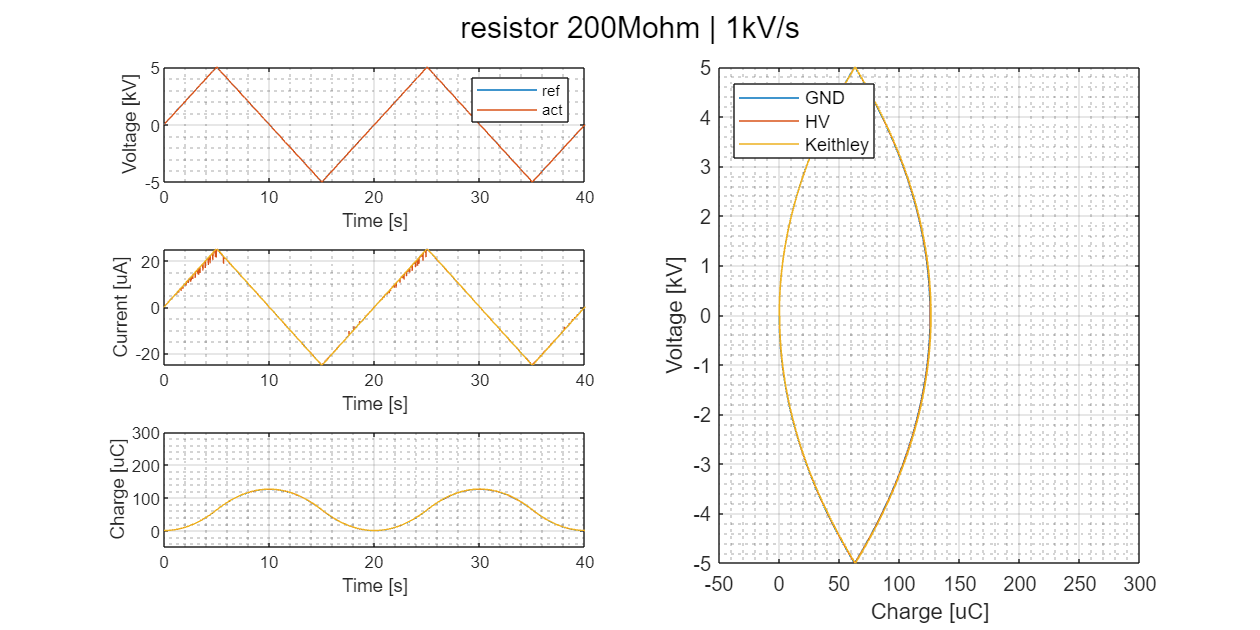


% raw_T80_s_30kV_010Hz_1000Hz_0050duty_02exp_000deg_000deg_000deg_000deg_2023_12_15_1432_42_DAQ.dat
% 12345678901234567890123456789012345678901234567890123456789012345678901234567890123456789012345678901234567890
% 0         1         2         3         4         5         6         7         8         9         0

for i = 1: length(FName)
    fName_DAQ = FName(i).name
    fName_Current = fName_DAQ;
    fName_Current(end-6: end + 9) = 'current_data.dat'



    tText = FName(i).text;
    k_keithley = str2num(fName_DAQ(9:11))*1e-6;
    flag_QI = fName_DAQ(7);
    time_init = FName(i).time_init;

    if flag_QI == 'I'
        [Time_DAQ, VoltageRef, ~, ~, ~, VoltageAct, CurrentDAQ, Current_Keithley, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~] = importfile_DAQ(fName_DAQ, k_keithley);
        % Charge_Keithley = nan(size(Time_DAQ));

    elseif flag_QI == 'Q'
        [Time_DAQ, VoltageRef, ~, ~, ~, VoltageAct, CurrentDAQ, Charge_Keithley, ~, ~, ~, ~, ~, ~, ~, ~, ~, ~] = importfile_DAQ(fName_DAQ, k_keithley);
        Current_Keithley = nan(size(Time_DAQ));
    end
    
    [Raw_GN, Raw_HV] = importfile_current(fName_Current);




    Time_CS = [-time_init: 1/FS_CS: (time_test) - 1/FS_CS];
    VoltageRef_CS = interp1(Time_DAQ, VoltageRef, Time_CS);
    VoltageAct_CS = interp1(Time_DAQ, VoltageAct, Time_CS);




    % Time_HV = [0: 1/FS_Current: (length(Raw_HV)-1)*1/FS_Current] - time_init;
    % Time_GN = [0: 1/FS_Current: (length(Raw_GN)-1)*1/FS_Current] - time_init;


    Current_GN = toAmps(Raw_GN(1: round((time_init + time_test)*FS_CS))); % without round() -> rounding error problem of float numbers
    Current_HV = toAmps(Raw_HV(1: round((time_init + time_test)*FS_CS)));

    Current_GN = Current_GN - mean(Current_GN(1:0.8*FS_CS));
    Current_HV = Current_HV - mean(Current_HV(1:0.8*FS_CS));
    Current_Keithley = Current_Keithley - mean(Current_Keithley(1:0.8*FS_DAQ));
    % Current_GN(isnan(Current_GN)) = 0;
    % Current_HV(isnan(Current_HV)) = 0;

    Charge_GN = current2charge(Current_GN, FS_CS, time_init);
    Charge_HV = current2charge(Current_HV, FS_CS, time_init);
    if flag_QI == 'I'
        Charge_Keithley = current2charge(Current_Keithley, FS_DAQ, time_init);
    elseif flag_QI == 'Q'
        Charge_Keithley = Charge_Keithley;
    end

    Current_GN_mod = Current_GN - (Charge_GN(end) - Charge_GN(time_init*FS_CS))/time_test;
    Current_HV_mod = Current_HV - (Charge_HV(end) - Charge_HV(time_init*FS_CS))/time_test;

    Charge_GN_mod = current2charge(Current_GN_mod, FS_CS, time_init);
    Charge_HV_mod = current2charge(Current_HV_mod, FS_CS, time_init);


    if flag_mod
        Current_GN = Current_GN_mod;
        Current_HV = Current_HV_mod;
        Charge_GN = Charge_GN_mod;
        Charge_HV = Charge_HV_mod;
    end
    f1 = figure(100 + i);
    % f1.Position(3) = f1.Position(4)*2;

    ax1 = subplot(3, 2, 1);
    hold on
    plot(Time_DAQ, VoltageRef*1e-3, DisplayName='ref')
    plot(Time_DAQ, VoltageAct*1e-3, DisplayName='act')
    setPlot([], 'Time [s]', Range_time, 'Voltage [kV]', Range_voltage, 'NorthEast')

    ax2 = subplot(3, 2, 3);

    hold on
    plot(Time_CS, Current_GN*1e6, DisplayName='GN')
    plot(Time_CS, Current_HV*1e6, DisplayName='HV')
    plot(Time_DAQ, Current_Keithley*1e6, DisplayName='Keithley')
    setPlot([], 'Time [s]', Range_time, 'Current [uA]', Range_current, 'none')
    % if max(abs([Current_GN(2:end); Current_HV(2:end)]))*1e9 > Range_current(2)
    %     ylim("auto")
    % end

    ax3 = subplot(3, 2, 5);
    hold on
    plot(Time_CS, Charge_GN*1e6, DisplayName='GN')
    plot(Time_CS, Charge_HV*1e6, DisplayName='HV')
    plot(Time_DAQ, Charge_Keithley*1e6, DisplayName='Keithley')

    setPlot([], 'Time [s]', Range_time, 'Charge [uC]', Range_charge, 'none')



    subplot(3, 2, [2 4 6])
    hold on
    plot(Charge_GN*1e6, VoltageAct_CS*1e-3, DisplayName='GND')
    plot(Charge_HV*1e6, VoltageAct_CS*1e-3, DisplayName='HV')
    plot(Charge_Keithley*1e6, VoltageAct*1e-3, DisplayName='Keithley')
    setPlot([], 'Charge [uC]', Range_charge, 'Voltage [kV]', Range_voltage, 'NorthWest')

    linkaxes([ax1, ax2, ax3], 'x')
    sgtitle(tText)


end

function Current = toAmps(Raw)
Raw(Raw == 0) = nan;
Bias = 3/2;
conversionFactorADC = (3/(2^16-1));
conversionFactorIn = 1/(11*2e3);
Current = ((Raw*conversionFactorADC)-Bias)*conversionFactorIn;
end

function [Times, VoltageRef1kV, VoltageRef2kV, VoltageRef3kV, VoltageRef4kV, Voltage1kV, Current1uA, Voltage2kV, Current2uA, Voltage3kV, Current3uA, Voltage4kV, Current4uA, Angle1V, Angle2V, force1V, force2V, force3V] = importfile_DAQ(filename, k_keithley, dataLines)
%IMPORTFILE Import data from a text file
%  [TIMES, VOLTAGEREF1KV, VOLTAGEREF2KV, VOLTAGEREF3KV, VOLTAGEREF4KV,
%  VOLTAGE1KV, CURRENT1UA, VOLTAGE2KV, CURRENT2UA, VOLTAGE3KV,
%  CURRENT3UA, VOLTAGE4KV, CURRENT4UA, ANGLE1V, ANGLE2V, FORCE1V,
%  FORCE2V, FORCE3V] = IMPORTFILE(FILENAME) reads data from text file
%  FILENAME for the default selection.  Returns the data as column
%  vectors.
%
%  [TIMES, VOLTAGEREF1KV, VOLTAGEREF2KV, VOLTAGEREF3KV, VOLTAGEREF4KV,
%  VOLTAGE1KV, CURRENT1UA, VOLTAGE2KV, CURRENT2UA, VOLTAGE3KV,
%  CURRENT3UA, VOLTAGE4KV, CURRENT4UA, ANGLE1V, ANGLE2V, FORCE1V,
%  FORCE2V, FORCE3V] = IMPORTFILE(FILE, DATALINES) reads data for the
%  specified row interval(s) of text file FILENAME. Specify DATALINES as
%  a positive scalar integer or a N-by-2 array of positive scalar
%  integers for dis-contiguous row intervals.
%
%  Example:
%  [Times, VoltageRef1kV, VoltageRef2kV, VoltageRef3kV, VoltageRef4kV, Voltage1kV, Current1uA, Voltage2kV, Current2uA, Voltage3kV, Current3uA, Voltage4kV, Current4uA, Angle1V, Angle2V, force1V, force2V, force3V] = importfile("C:\Users\fukushima\Desktop\20231024_sensorTest\raw_HASEL_HVon_r_80kV_000Hz_1000Hz_0050duty_04exp_000deg_000deg_000deg_000deg_2023_10_24_1818_03_DAQ.dat", [2, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 25-Oct-2023 07:32:16

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 3
    dataLines = [2, Inf];
end

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 18);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "VoltageRef1kV", "VoltageRef2kV", "VoltageRef3kV", "VoltageRef4kV", "Voltage1kV", "Current1uA", "Voltage2kV", "Current2uA", "Voltage3kV", "Current3uA", "Voltage4kV", "Current4uA", "Angle1V", "Angle2V", "force1V", "force2V", "force3V"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable(filename, opts);

%% Convert to output type
Times = tbl.Times;
VoltageRef1kV = tbl.VoltageRef1kV*1e3;
VoltageRef2kV = tbl.VoltageRef2kV;
VoltageRef3kV = tbl.VoltageRef3kV;
VoltageRef4kV = tbl.VoltageRef4kV;
Voltage1kV = tbl.Voltage1kV*1e3;
Current1uA = tbl.Current1uA*2e-3/10;
Voltage2kV = -tbl.Voltage2kV*k_keithley/2; % Keithley current
Current2uA = tbl.Current2uA;
Voltage3kV = tbl.Voltage3kV;
Current3uA = tbl.Current3uA;
Voltage4kV = tbl.Voltage4kV;
Current4uA = tbl.Current4uA;
Angle1V = tbl.Angle1V;
Angle2V = tbl.Angle2V;
force1V = tbl.force1V;
force2V = tbl.force2V;
force3V = tbl.force3V;
end

function [A0764E41E670, A0764E421D14] = importfile_current(filename, dataLines)
%IMPORTFILE Import data from a text file
%  [A0764E41E670, A0764E421D14] = IMPORTFILE(FILENAME) reads data from
%  text file FILENAME for the default selection.  Returns the data as
%  column vectors.
%
%  [A0764E41E670, A0764E421D14] = IMPORTFILE(FILE, DATALINES) reads data
%  for the specified row interval(s) of text file FILENAME. Specify
%  DATALINES as a positive scalar integer or a N-by-2 array of positive
%  scalar integers for dis-contiguous row intervals.
%
%  Example:
%  [A0764E41E670, A0764E421D14] = importfile("C:\Users\fukushima\Desktop\20231024_sensorTest\raw_HASEL_HVon_r_80kV_000Hz_1000Hz_0050duty_04exp_000deg_000deg_000deg_000deg_2023_10_24_1818_03_current_data.dat", [2, Inf]);
%
%  See also READTABLE.
%
% Auto-generated by MATLAB on 25-Oct-2023 07:30:36

%% Input handling

% If dataLines is not specified, define defaults
if nargin < 2
    dataLines = [2, Inf];
end

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["A0764E41E670", "A0764E421D14"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable(filename);

%% Convert to output type
A0764E41E670 = -tbl.A0764E41E670;
A0764E421D14 = -tbl.A0764E421D14;
end


function Charge = current2charge(Current, FS, time_init)
Charge = cumtrapz(Current)/FS;
Charge = Charge - Charge(round(time_init*FS));

end

function setPlot(label_title, label_x, Range_x, label_y, Range_y, position_legend)
fg = gcf();
fg.Position(3) = fg.Position(4)*2;
% fg.GraphicsSmoothing = 'off';

title(label_title)
xlabel(label_x)
ylabel(label_y)
xlim(Range_x)
ylim(Range_y)
if contains(position_legend, 'none', IgnoreCase=true)
    legend('off')
else
    legend('Location', position_legend)
end
grid on
grid minor
box on
end

function [rms_noise, snr] = plot_psd(data,FS, A, label)
rms_signal = A/sqrt(2); % assumption of full range sin signal: rms(Asin(wt)) = A/sqrt(2)
rms_noise = rms(data - mean(data));
snr = (rms_signal/rms_noise);

window = floor(length(data)/10);
[pxx,f] = pwelch(data/A, gausswin(window), [], [], FS);

psd = pow2db(pxx);
plot(f,psd, 'DisplayName', label);
xlim([0, FS/2]);

[pks,locs, peakwidth, peakProminence] =findpeaks(psd,f);
peaks_prominence = find(peakProminence>10);% &peakwidth>10);
text(gca,locs(peaks_prominence)-5,pks(peaks_prominence)+.2,[num2str(round(locs(peaks_prominence)))])

end